if exist("wcli", "var")
    clib.webcface.wcfClose(wcli);
end

clear all;
close all;

webcfaceのロードと初期化

addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "C:\Users\mech-user\3a_pro\ik\webcface\webcfaceInterface.dll"
               Libraries: ["webcface.dll"    "spdlogd.dll"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 21228


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli);

fk, ikの初期化

% Generate robot
%robot = loadrobot("kinovaGen3","DataFormat","column");
robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

p0 = tform2trvec(getTransform(robot, q, "arm_link7_link", "base_link"));
x0 = p0(1)

x0 = 0.5084

y0 = p0(2)

y0 = -0.0300

z0 = 0.2976

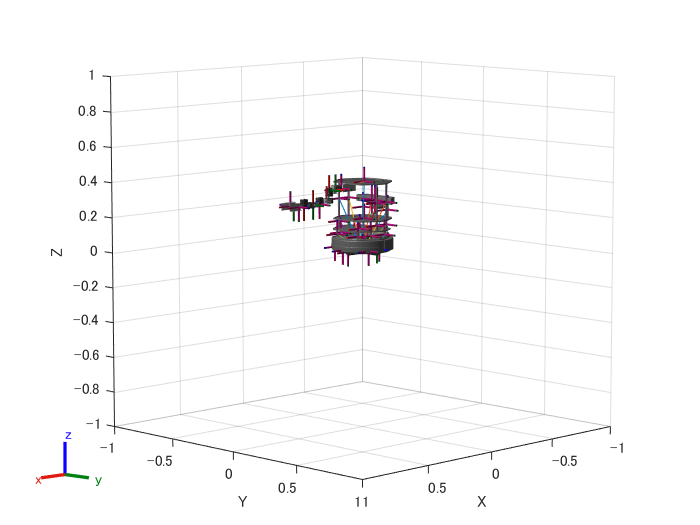

z0 = p0(3)

% Define IK solver
ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
%weights = [1, 1, 1, 1, 1, 1];
endEffector = 'arm_link7_link';

初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "move_servo", qs)

ans = ""

show(robot, q);

xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])

値を入れてikを解き、送る

x = 0.3

x = 0.3000

y = -0.03000000000000007

y = -0.0300

z = 0.31

z = 0.3100

q = ik(endEffector,trvec2tform([x y z]),weights,q);
qs = ["0" "0" "0" "0" "0" "0" "0"];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    % todo: 小数渡すとエラー出すので整数にしているがあとでなおす
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "move_servo", qs)

次を使用中のエラー: clib.webcface.wcfFuncRunS
ユーザー ライブラリがメッセージと共に SeparateProcessException をスローしました:'unsigned byte integer is less than minimum'。

show(robot, q);
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])

サーボをoffにする

 
clib.webcface.wcfFuncRunS(wcli, "dynamixel", "free_servo", [])

ans = ""